**Spliting Data from Previously normalized data**

data_bayesian=cat(2,x2,y2);
training_set=data_bayesian(tr_lm.trainInd,:);

training_set =          0         0         0         0         0    0.4178    0.5425
         0         0    0.0500         0         0    0.4221    0.5364
         0         0    0.1000         0         0    0.4265    0.5328
         0         0    0.1500         0         0    0.4311    0.5309
         0         0    0.2500         0         0    0.4412    0.5297
         0         0    0.3000         0         0    0.4468    0.5297
         0         0    0.3500         0         0    0.4527    0.5300
         0         0    0.4500         0         0    0.4655    0.5306
         0         0    0.5000         0         0    0.4725    0.5309
         0         0    0.5500         0         0    0.4798    0.5312


validation_set=data_bayesian(tr_lm.valInd,:);

validation_set =          0         0    0.2000         0         0    0.4360    0.5300
         0         0    0.4000         0         0    0.4589    0.5303
         0         0    0.6000         0         0    0.4876    0.5315
         0    0.2500    0.2500         0         0    0.4532    0.4567
         0    0.2500    0.3000         0         0    0.4592    0.4631
         0    0.2500    0.5000         0         0    0.4876    0.4849
         0    0.5000         0         0         0    0.4563    0.4139
         0    0.5000    0.1500         0         0    0.4627    0.3764
         0    0.5000    0.4000         0         0    0.4934    0.4163
         0    0.5000    0.5500         0         0    0.5196    0.4418


x2_bay_training=training_set(:,1:5);
y2_bay_training=training_set(:,6:7);
x2_bay_val=validation_set(:,1:5);
y2_bay_val=validation_set(:,6:7);

**Bayesian regulation**

xt_bay_train=x2_bay_training';
yt_bay_train=y2_bay_training';
xt_bay_val=x2_bay_val';
yt_bay_val=y2_bay_val';
hiddenLayerSize=50;
bay=fitnet(hiddenLayerSize,'trainbr');
bay.divideParam.trainRatio=100/100;
bay.divideParam.valRatio=0/100;
bay.divideParam.testRatio=0/100;
[bay,tr_bay]=train(bay,xt_bay_train,yt_bay_train);

**Performence**

training set

Y_bay=bay(xt_bay_train);
Yt_bay=yt_bay_train;
yTrain_bay=(Y_bay'.*(max(y)-min(y))+min(y))';
yTrainTrue_bay=(Yt_bay'.*(max(y)-min(y))+min(y))';
perf_P_bay=rMetrics(yTrainTrue_bay(1,:),yTrain_bay(1,:));
perf_Nu_bay=rMetrics(yTrainTrue_bay(2,:),yTrain_bay(2,:));
row_names_bay=array2table({'Pressure_ratio';'Nusselt ratio'});
T_bay_train=cat(1,perf_P_bay,perf_Nu_bay);
T_bay_train=cat(2,row_names_bay,T_bay_train)

T_bay_train = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.014687     0.0004072    0.020179    0.99635    1.2986
    {'Nusselt ratio' }    0.010651    0.00023576    0.015354     0.9897    1.2411


Validation set

Y_val_bay=bay(xt_bay_val);
Yt_val_bay=yt_bay_val;
yVal_bay=(Y_val_bay'.*(max(y)-min(y))+min(y))';
yValTrue_bay=(Yt_val_bay'.*(max(y)-min(y))+min(y))';
perf_P_bay=rMetrics(yValTrue_bay(1,:),yVal_bay(1,:));
perf_Nu_bay=rMetrics(yValTrue_bay(2,:),yVal_bay(2,:));
row_names_bay=array2table({'Pressure_ratio';'Nusselt ratio'});
T_bay_val=cat(1,perf_P_bay,perf_Nu_bay);
T_bay_val=cat(2,row_names_bay,T_bay_val)

T_bay_val = 2×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.014875    0.00042899    0.020712    0.99675    1.3276
    {'Nusselt ratio' }    0.011187    0.00030169    0.017369    0.98683    1.3281


**Plot**

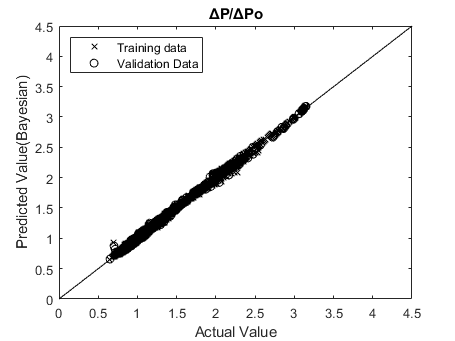

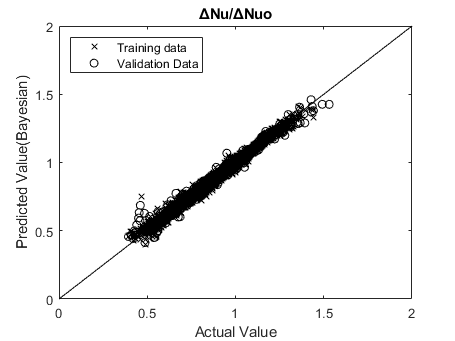

for i=1:2
    figure()
    set(gca,'box','on')
    hold on;
    plot(yTrainTrue_bay(i,:),yTrain_bay(i,:),'x','Color','k');
    plot(yValTrue_bay(i,:),yVal_bay(i,:),'o','Color','k');
    plot(0:5,0:5,'Color','k');
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Training data','Validation Data','','Location','northwest')
    xlabel('Actual Value')
    ylabel('Predicted Value(Bayesian)')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_BAY_4=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_BAY_4)
    else
        Plot_BAY_4=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_BAY_4)
    end
end

**Optimization**

%run to clear previous variable value
clear("rms_train_bay",'rms_val_bay','r2_train_bay',"r2_val_bay",'mape_train_bay',"mape_val_bay",'name_bay')

%select all and press ctrl+T to enable section
hiddenLayerNo=[1,2,3];
for i=1:50

    %defining the architecture of the Ann
    hiddenLayerSize=i;
    bay=fitnet(hiddenLayerSize,'trainbr');
    %training of Ann
    [bay,tr_bay]=train(bay,xt_bay_train,yt_bay_train);
   
    Y_val_bay=bay(xt_bay_val);
    Yt_val_bay=yt_bay_val;
    Y_bay=bay(xt_bay_train);
    Yt_bay=yt_bay_train;

    yTrain_bay=(Y_bay'.*(max(y)-min(y))+min(y))';
    yTrainTrue_bay=(Yt_bay'.*(max(y)-min(y))+min(y))';
    yVal_bay=(Y_val_bay'.*(max(y)-min(y))+min(y))';
    yValTrue_bay=(Yt_val_bay'.*(max(y)-min(y))+min(y))';
    %RMSE
    for j=1:2
        rms_train_bay(i,j)=sqrt(mean(((yTrain_bay(j,:)-yTrainTrue_bay(j,:)).^2),2));
    end   
    for j=1:2
        rms_val_bay(i,j)=sqrt(mean(((yVal_bay(j,:)-yValTrue_bay(j,:)).^2),2));
    end
    %R2
    for j=1:2
        r2_train_bay(i,j)=1 - (sum(((yTrainTrue_bay(j,:) - yTrain_bay(j,:)).^2),2)/sum(((yTrainTrue_bay(j,:) - mean(yTrainTrue_bay(j,:),2)).^2),2));
    end   
    for j=1:2
        r2_val_bay(i,j)=1 - (sum(((yValTrue_bay(j,:) - yVal_bay(j,:)).^2),2)/sum(((yValTrue_bay(j,:) - mean(yValTrue_bay(j,:))).^2),2));
    end
    %mape
    for j=1:2
        mape_train_bay(i,j)=mean(abs((yTrainTrue_bay(j,:)-yTrain_bay(j,:))./yTrainTrue_bay(j,:)),2).*100;
    end   
    for j=1:2
        mape_val_bay(i,j)=mean(abs((yValTrue_bay(j,:)-yVal_bay(j,:))./yValTrue_bay(j,:)),2).*100;
    end

   name_bay{i} = ['Hidden Layer size: ' num2str(i,'%d')];
   Ta_bay=array2table(rms_train_bay,"VariableNames",{'RMS(delP/delPo)','RMS(delNu/delNuo)'});
   Ta_bay.Properties.RowNames=name_bay;
   Tb_bay=array2table(rms_val_bay,"VariableNames",{'RMS(delP/delPo)','RMS(delNu/delNuo)'});
   Tb_bay.Properties.RowNames=name_bay;
end

%select all and press ctrl+T to enable section
Ta_bay

Ta_bay = 50×2 table
                             RMS(delP/delPo)    RMS(delNu/delNuo)
                             _______________    _________________

    Hidden Layer size: 1          0.3279             0.10839     
    Hidden Layer size: 2          0.1541             0.10927     
    Hidden Layer size: 3         0.13538             0.10824     
    Hidden Layer size: 4         0.17265            0.095442     
    Hidden Layer size: 5        0.092411            0.084317     
    Hidden Layer size: 6         0.10751            0.064338     
    Hidden Layer size: 7        0.095917            0.080252     
    Hidden Layer size: 8        0.087128            0.066719     
    Hidden Layer size: 9        0.078922            0.052272     
    Hidden Layer size: 1

Tb_bay

Tb_bay = 50×2 table
                             RMS(delP/delPo)    RMS(delNu/delNuo)
                             _______________    _________________

    Hidden Layer size: 1          0.3057             0.11418     
    Hidden Layer size: 2         0.15226              0.1152     
    Hidden Layer size: 3         0.13272             0.11413     
    Hidden Layer size: 4         0.17549             0.10099     
    Hidden Layer size: 5         0.08809            0.089536     
    Hidden Layer size: 6         0.10562            0.068644     
    Hidden Layer size: 7        0.092275            0.086543     
    Hidden Layer size: 8        0.084362            0.072812     
    Hidden Layer size: 9        0.074115            0.057038     
    Hidden Layer size: 1

writetable(Ta_bay,'D:/Matlab Drive/Research/Table/Performence_bay(training).xlsx','Sheet',1)
writetable(Tb_bay,'D:/Matlab Drive/Research/Table/Performence_bay(validation).xlsx','Sheet',1)

**Select Optimum no of neuron in hidden layer(rmse)**

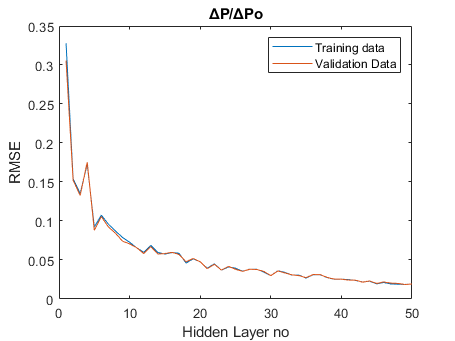

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,rms_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
plot(1:i,rms_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(rmse).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

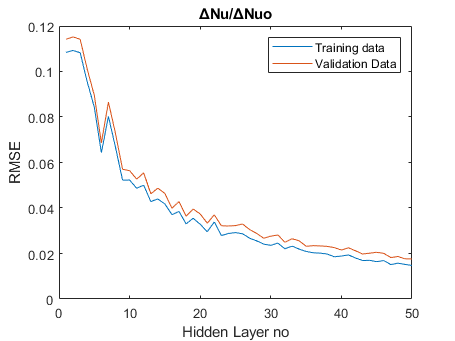

%for nusselt
plot(1:i,rms_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
plot(1:i,rms_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(rmse).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

**Select Optimum no of neuron in hidden layer(r2) **

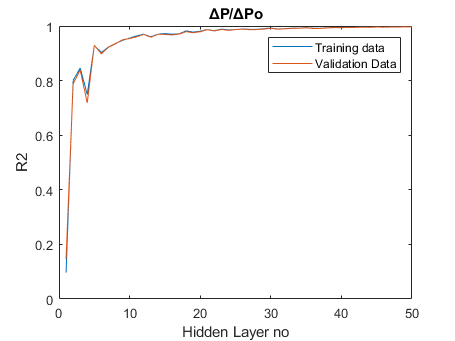

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,r2_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔP/ΔPo')
plot(1:i,r2_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(r2).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

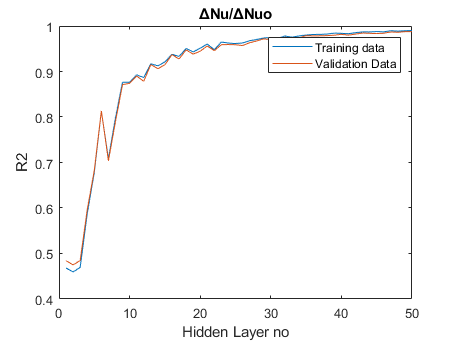

%for nusselt
plot(1:i,r2_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔNu/ΔNuo')
plot(1:i,r2_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(r2).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

**Select Optimum no of neuron in hidden layer(mape)**

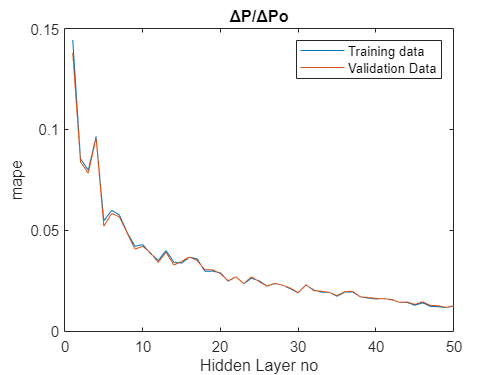

%select all and press ctrl+T to enable section
%for pressure
plot(1:i,mape_train_bay(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔP/ΔPo')
plot(1:i,mape_val_bay(:,1));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔP÷ΔPo_optimisation(mape).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;

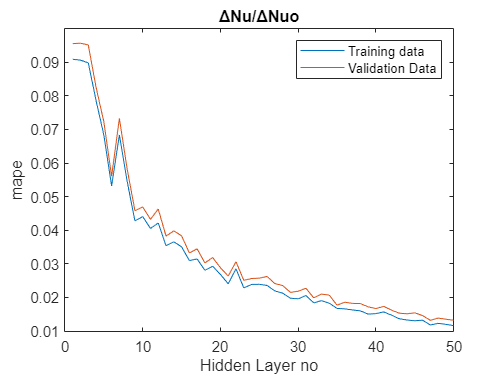

%for nusselt
plot(1:i,mape_train_bay(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔNu/ΔNuo')
plot(1:i,mape_val_bay(:,2));
Plot_BAY_3=sprintf('D:/Matlab Drive/Research/Figure/BAY/ΔNu÷ΔNuo_optimisation(mape).bmp');
saveas(gcf,Plot_BAY_3)
legend('Training data','Validation Data');hold off;